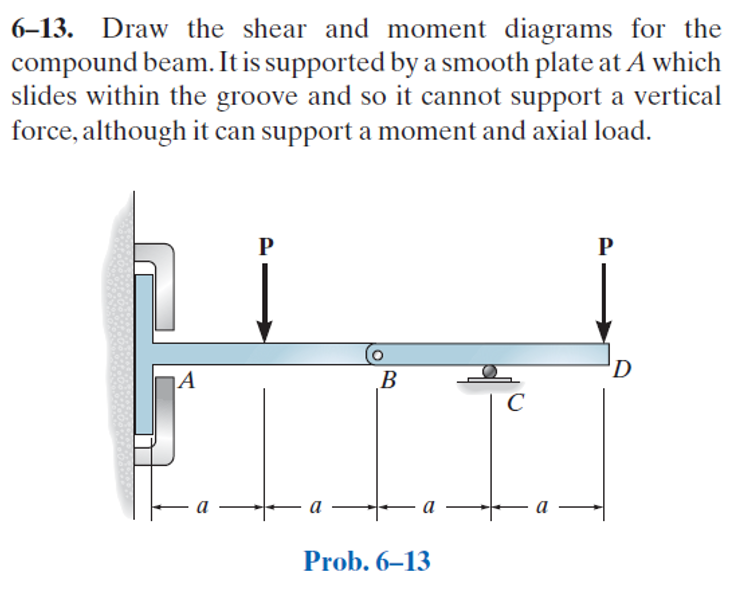

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-13P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-13P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

P = sym('P');
a = sym('a', 'positive');

# beam

b = beam;
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('concentrated', 'force', -P, a);
b = b.add('hinge', 'force', 'Hb', 2*a);
b = b.add('reaction', 'force', 'Rc', 3*a);
b = b.add('concentrated', 'force', -P, 4*a);
b.L = 4*a;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{P\,a\,\left(5\,a^{2}+3\,x^{2}\right)}{6\,\text{E}\,\text{I}} & \text{ if }x\leq a\\ \frac{P\,\left(6\,a^{3}-3\,a^{2}\,x+6\,a\,x^{2}-x^{3}\right)}{6\,\text{E}\,\text{I}} & \text{ if }a<x\wedge x\leq 2\,a\\ \frac{P\,\left(3\,a-x\right)\,\left(18\,a^{2}-3\,a\,x+x^{2}\right)}{6\,\text{E}\,\text{I}} & \text{ if }2\,a<x\wedge x\leq 3\,a\\ \frac{P\,x\,\left(3\,a-x\right)\,\left(9\,a-x\right)}{6\,\text{E}\,\text{I}} & \text{ if }3\,a<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{P\,a\,x}{\text{E}\,\text{I}} & \text{ if }x\leq a\\ -\frac{P\,\left(a^{2}-4\,a\,x+x^{2}\right)}{2\,\text{E}\,\text{I}} & \text{ if }a<x\wedge x\leq 2\,a\\ -\frac{P\,\left(9\,a^{2}-4\,a\,x+x^{2}\right)}{2\,\text{E}\,\text{I}} & \text{ if }2\,a<x\wedge x\leq 3\,a\\ \frac{P\,\left(9\,a^{2}-8\,a\,x+x^{2}\right)}{2\,\text{E}\,\text{I}} & \text{ if }3\,a<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} P\,a & \text{ if }x\leq a\\ P\,\left(2\,a-x\right) & \text{ if }a<x\wedge x\leq 3\,a\\ -P\,\left(4\,a-x\right) & \text{ if }3\,a<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x\leq a\\ -P & \text{ if }a<x\wedge x\leq 3\,a\\ P & \text{ if }3\,a<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & -P\,a\\ \mathrm{Rc} & 2\,P \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & P \end{array}\right)$$

# shear and moment diagram

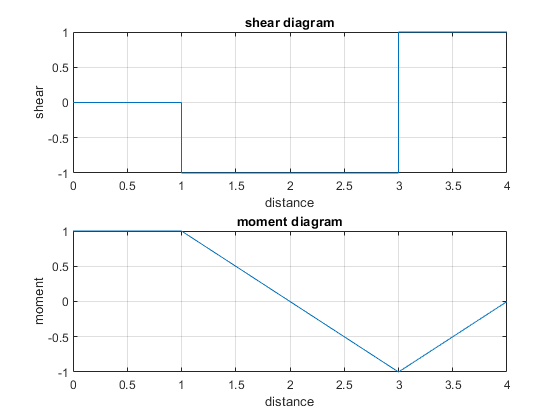

beam.shear_moment(m, v, [0 4], [P a], 1);

# clean up

addvar(y);
new_assum = assumptions;